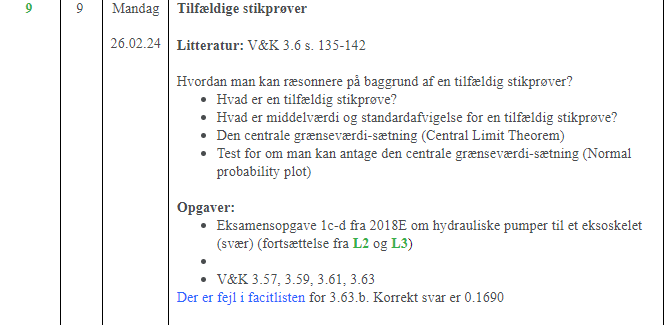

% clc; clear;

n_samples =4230

n_samples = 4230

sample_size = 100

sample_size = 100

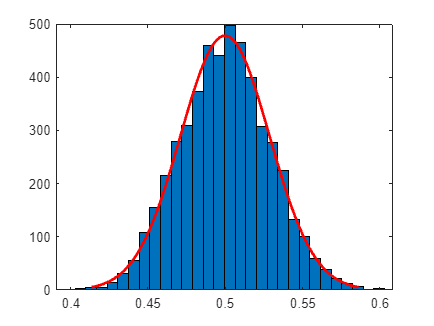


tic
for i = 1:n_samples
    x(i) = mean(rand(sample_size,1));
end

figure
% histogram(x, 20)
histfit(x,30,"normal")

toc

Elapsed time is 0.101434 seconds.


n_samples =1330

n_samples = 1330

sample_size = 100

sample_size = 100

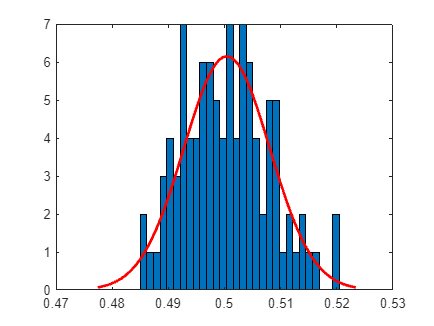


tic
d3arr = rand(1,sample_size,n_samples);

md3 = mean(d3arr,3);

histfit(md3, 30, "normal")

toc

Elapsed time is 0.166883 seconds.


fitdist(x',"normal")

ans =   NormalDistribution

  Normal distribution
       mu =  0.499822   [0.499024, 0.50062]
    sigma = 0.0287834   [0.0282301, 0.029359]



var(x)

ans = 8.2848e-04


[h,c,v,b] = vartest(x, 0.01)

h = 1

c = 0

v = 1.0e-03 *

    0.7969    0.8619


b = struct with fields:
    chisqstat: 414.1595
           df: 4999


clc; clear;

% Data indlæses
data = xlsread("Eksamenssæt\Eksamenssæt 2018E\Data_M4STI1_2018E (1).xlsx", 'A:A');

% Opgave a
D = sort(data)

D =     96
    97
   102
   102
   104
   106
   108
   110



n = length(D)       % Antal datapunkter

n = 8

mdl = mean(data)    % Stikprøvens middelværdi

mdl = 103.1250

stdafv = std(D)  % Populationsdata, derfor n-1

stdafv = 4.9407


afv = [mdl + stdafv; mdl - stdafv]

afv =   108.0657
   98.1843



max(D), min(D)

ans = 110

ans = 96


% Det ses at gennemsnittet +/- 1 standard afvigelse ligger indenfor rækkeviden min, max i datasættet

% Opgave b
D = data;
max(D)

ans = 110


stdafv = std(D)

stdafv = 4.9407


middel = mean(D)

middel = 103.1250

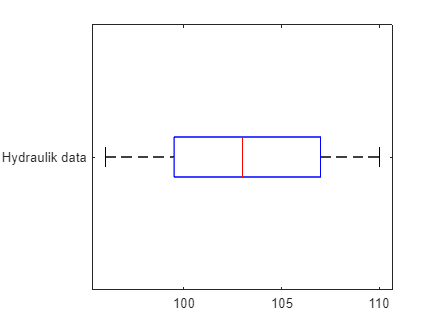


figure
boxplot(D, 'Orientation','horizontal', 'Labels',{'Hydraulik data'})

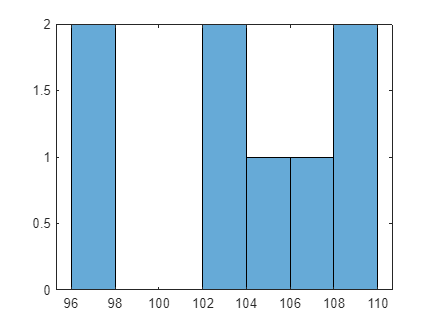


figure
histogram(D, floor(min(D)):2:ceil(max(D)))


stemleafplot(D)

   9 | 6 7
  10 | 2 2 4 6 8
  11 | 0
key: 36|5 = 365
stem unit: 10
leaf unit: 1




prctile(D, [25,50,75])

ans =    99.5000  103.0000  107.0000


% Opgave c
% Observerede værdier
mu_obs = 105;
std_obs = 5;

% Udregnede stikprøve værdier
Ybar = mdl;
std_obs = stdafv;

% Den centrale grænseværdisætning antages
Z = (Ybar - mu_obs)/(std_obs/sqrt(n))

Z = -1.0734


% P(Z >= -1.0734 & Z <= -1.0734)
ssh1 = normcdf(Z) % Ssh for at den er større end

ssh1 = 0.1415

ssh2 = 1 - normcdf(abs(Z))

ssh2 = 0.1415

ssh3 = ssh1 + ssh2

ssh3 = 0.2831


losningsforslag = 2*(1-normcdf(abs(Z)))

losningsforslag = 0.2831

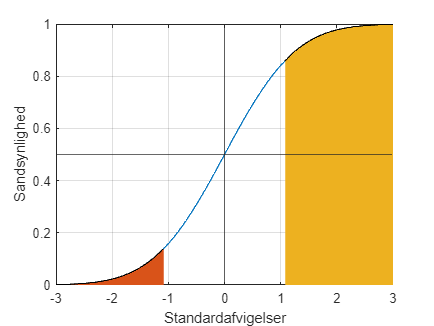

dist = makedist("Normal","mu",0,"sigma",1);
x = -3:0.01:3;

df = cdf(dist, x);
df1 = pdf(dist, x);

% Plot for forståelse
plot(x, df), xline(0), yline(0.5), grid(), xlabel("Standardafvigelser"), ylabel("Sandsynlighed")
hold on


x_less_Z = find(x < Z);
x_larger_Z = find(x > abs(Z));

% Komulativ fordelings plot
% mindre end Z
area(x(1, 1:length(x_less_Z)), df(1, 1:length(x_less_Z)));

% Større end Z
area(x(1, x_larger_Z(1):end), df(1, x_larger_Z(1):end));


hold off

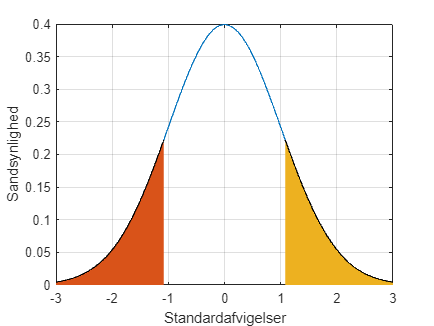


% Ssh plot
plot(x, df1), xlabel("Standardafvigelser"), ylabel("Sandsynlighed"), grid()
hold on
% mindre end Z
area(x(1, 1:length(x_less_Z)), df1(1, 1:length(x_less_Z)));

% Større end Z
area(x(1, x_larger_Z(1):end), df1(1, x_larger_Z(1):end));
hold off

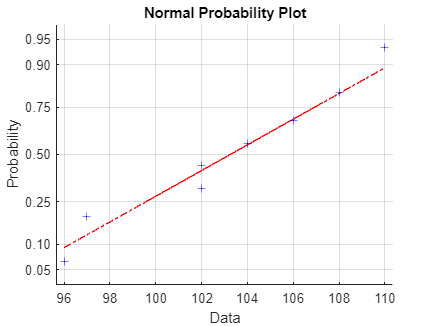


normplot(D)